# Partition Data into Two Clusters

Randomly generate the sample data.

clc
clear

rng default; % For reproducibility
% X = [randn(100,2)*0.75+ones(100,2);
%     randn(100,2)*0.5-ones(100,2)];

instance = xlsread('A-n33-k6');

X = instance(:,2:3)

X =     34    31
    45    55
    70    80
    81    70
    85    61
    59    55
    45    60
    50    64
    80    64
    75    90


depot = instance(1,:)

depot =      1    34    31     0


ans = 34

X(1,:) = []

X =     45    55
    70    80
    81    70
    85    61
    59    55
    45    60
    50    64
    80    64
    75    90
    25    40


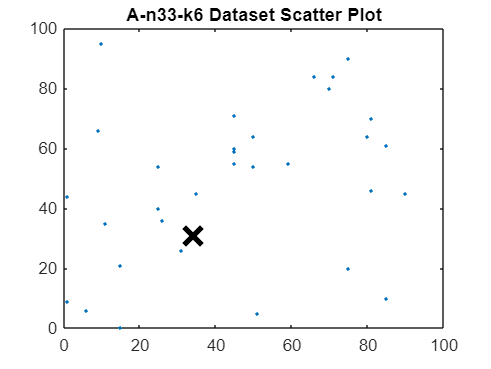

figure;
plot(X(:,1),X(:,2),'.');
hold on
plot(depot(:,2),depot(:,3),'kx','MarkerSize',15,'LineWidth',3) 
title 'A-n33-k6 Dataset Scatter Plot';

There appears to be two clusters in the data.

Partition the data into two clusters, and choose the best arrangement out of five initializations. Display the final output.

opts = statset('Display','final');
[idx,C] = kmeans(X,6,'Distance','sqeuclidean','MaxIter',10000000,...
    'Replicates',10000,'Options',opts); %cityblock, cosine, sqeuclidean

Replicate 1, 3 iterations, total sum of distances = 7043.19.
Replicate 2, 1 iterations, total sum of distances = 7334.95.
Replicate 3, 2 iterations, total sum of distances = 6147.39.
Replicate 4, 6 iterations, total sum of distances = 6238.55.
Replicate 5, 1 iterations, total sum of distances = 8148.11.
Replicate 6, 2 iterations, total sum of distances = 5951.46.
Replicate 7, 2 iterations, total sum of distances = 5951.46.
Replicate 8, 2 iterations, total sum of distances = 6943.33.
Replicate 9, 2 iterations, total sum of distances = 8383.99.
Replicate 10, 3 iterations, total sum of distances = 5920.23.
Replicate 11, 6 iterations, total sum of distances = 6638.61.
Replicate 12, 3 iterations, total sum of distances = 6638.61.
Replicate 13, 3 iterations, total sum of distances = 7286.36.
Replicate 14, 3 iterations, total sum of distances = 6178.63.
Replicate 15, 2 iterations, total sum of distances = 7156.93.
Replicate 16, 4 iterations, total sum of distances = 6147.39.
Replicate 17, 2 i

By default, the software initializes the replicates separately using *k*-means++.

Plot the clusters and the cluster centroids.

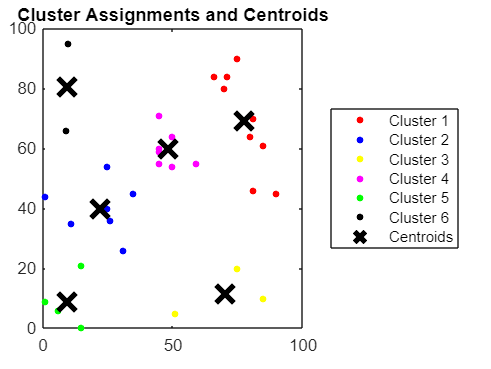

figure;
plot(X(idx==1,1),X(idx==1,2),'r.','MarkerSize',12)
hold on
plot(X(idx==2,1),X(idx==2,2),'b.','MarkerSize',12)
hold on
plot(X(idx==3,1),X(idx==3,2),'y.','MarkerSize',12)
hold on
plot(X(idx==4,1),X(idx==4,2),'m.','MarkerSize',12)
hold on
plot(X(idx==5,1),X(idx==5,2),'g.','MarkerSize',12)
hold on
plot(X(idx==6,1),X(idx==6,2),'k.','MarkerSize',12)
plot(C(:,1),C(:,2),'kx',...
     'MarkerSize',15,'LineWidth',3) 
legend('Cluster 1','Cluster 2','Cluster 3','Cluster 4','Cluster 5','Cluster 6','Centroids',...
       'Location','eastoutside') %legend('Location','NW')
title 'Cluster Assignments and Centroids'
hold off

red_cluster = [X(idx==1,1) X(idx==1,2)]

red_cluster =     70    80
    81    70
    85    61
    80    64
    75    90
    71    84
    66    84
    81    46
    90    45


blue_cluster =[X(idx==2,1) X(idx==2,2)]

blue_cluster =     25    40
     1    44
    35    45
    25    54
    11    35
    31    26
    26    36


yellow_cluster = [X(idx==3,1) X(idx==3,2)]

yellow_cluster =     85    10
    75    20
    51     5


magenta_cluster = [X(idx==4,1) X(idx==4,2)]

magenta_cluster =     45    55
    59    55
    45    60
    50    64
    50    54
    45    59
    45    71


green_cluster = [X(idx==5,1) X(idx==5,2)]

green_cluster =      1     9
    15    21
    15     0
     6     6


black_cluster = [X(idx==6,1) X(idx==6,2)]

black_cluster =      9    66
    10    95


after_cluster = [red_cluster; blue_cluster; yellow_cluster; magenta_cluster; green_cluster; black_cluster]

after_cluster =     70    80
    81    70
    85    61
    80    64
    75    90
    71    84
    66    84
    81    46
    90    45
    25    40


for i = 1:length(after_cluster)
    %instance;
    %after_cluster(i,1)
    %after_cluster(i,2)
    %instance(i+1,2)
    %instance(i+1,3)
    %find(after_cluster(i,1) && after_cluster(i,2) == instance(i+1,2) && instance(i+1,3)) = instance(i+1,1)
end

ans = 70

ans = 80

ans = 45

ans = 55

find = 31

ans = 81

ans = 70

ans = 70

ans = 80

find = 3

ans = 85

ans = 61

ans = 81

ans = 70

find = 3

ans = 80

ans = 64

ans = 85

ans = 61

find = 3

ans = 75

ans = 90

ans = 59

ans = 55

find = 3

ans = 71

ans = 84

ans = 45

ans = 60

find = 3

ans = 66

ans = 84

ans = 50

ans = 64

find = 3

ans = 81

ans = 46

ans = 80

ans = 64

find = 3

ans = 90

ans = 45

ans = 75

ans = 90

find = 3

ans = 25

ans = 40

ans = 25

ans = 40

find = 3

ans = 1

ans = 44

ans = 9

ans = 66

find = 3

ans = 35

ans = 45

ans = 1

ans = 44

find = 3

ans = 25

ans = 54

ans = 50

ans = 54

find = 3

ans = 11

ans = 35

ans = 35

ans = 45

find = 15

ans = 31

ans = 26

ans = 71

ans = 84

find = 15

ans = 26

ans = 36

ans = 1

ans = 9

find = 15

ans = 85

ans = 10

ans = 25

ans = 54

find = 15

ans = 75

ans = 20

ans = 45

ans = 59

find = 15

ans = 51

ans = 5

ans = 45

ans = 71

find = 15

ans = 45

ans = 55

ans = 66

ans = 84

find = 15

ans = 59

ans = 55

ans = 11

ans = 35

find = 15

ans = 45

ans = 60

ans = 81

ans = 46

find = 15

ans = 50

ans = 64

ans = 85

ans = 10

find = 15

ans = 50

ans = 54

ans = 75

ans = 20

find = 15

ans = 45

ans = 59

ans = 15

ans = 21

find = 15

ans = 45

ans = 71

ans = 90

ans = 45

find = 15

ans = 1

ans = 9

ans = 15

ans = 0

find = 15

ans = 15

ans = 21

ans = 31

ans = 26

find = 15

ans = 15

ans = 0

ans = 10

ans = 95

find = 15

ans = 6

ans = 6

ans = 6

ans = 6

find = 31

ans = 9

ans = 66

ans = 51

ans = 5

find = 31

ans = 10

ans = 95

ans = 26

ans = 36

find = 31

You can determine how well separated the clusters are by passing `idx` to [silhouette](docid:stats_ug.f3984482).

*Copyright 2015 The MathWorks, Inc.*

%openExample('stats/ClusterDataUsingParallelComputingExample')

%openExample('stats/TrainAkMeansClusteringAlgorithm2Example')

%openExample('stats/PartitionDataIntoTwoClustersExample')